# Model Predictive Control (MPC) - Project

## Final Challenge: Bringing the Crane Under Control

Welcome to the exercises of the Model Predictive Control course! The following toolboxes are useful for the project:

- Symbolic Math Toolbox 

- Control System Toolbox

- Model Predictive Control Toolbox

clear; clf; clc;

With the CSTR now running smoothly, production stabilized, and Mr. Controlly visibly relaxed for the first time in weeks, you’re already shifting focus to documentation and simulation cleanup.

But your peace is short-lived. Controlly appears once more at your desk - this time with a folder under his arm and a look of renewed determination.

*“Listen,”* he says, *“you’ve done excellent work on the reactor. But there’s one more system that’s still giving us trouble: the crane.”*

You nod slowly. Of course - the overhead crane, the same one you looked at briefly during one of the earlier task. Back then, it was all impulse responses and noisy measurements. Now it’s time to take things seriously.

*“Patrick has spent the last few weeks building a proper model,”* Controlly explains. *“Turns out the crane behaves almost linearly - except for one thing: when the actuator commands high accelerations, the system starts slipping. That’s where it gets nonlinear.”*

Patrick has indeed done solid work: he’s derived a **state-space model** that captures the main dynamics of the crane. However, **nonlinear effects in the input channel, **due to friction, cable slack, or motor limitations, cause deviations especially at high control inputs.

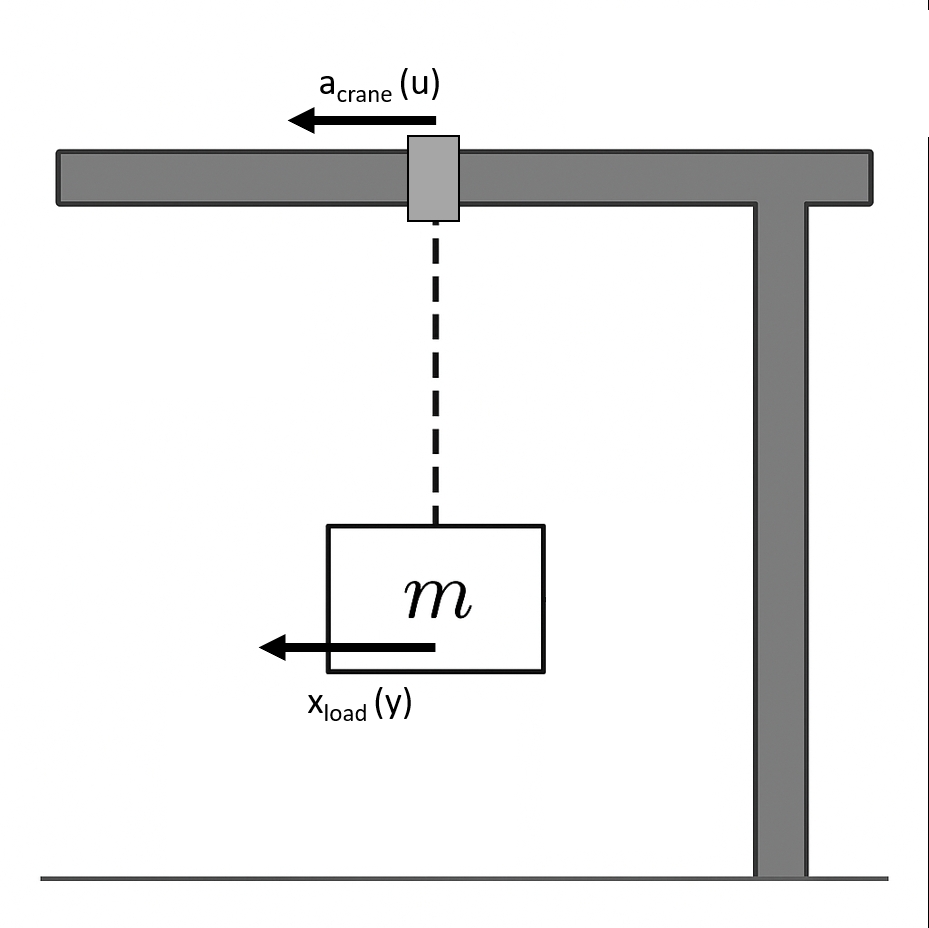

Various impulse response experiments were carried out for this purpose. The crane was **accelerated** (impulse for on sample) and the crane speed was measured *(be careful: Noise!)*. The state vector $\underline{x} ={\left\lbrack \begin{array}{cccc}
x_{\textrm{load}}  & v_{\textrm{load}}  & x_{\textrm{crane}}  & v_{\textrm{crane}} 
\end{array}\right\rbrack }^{\mathrm{T}}$ and the position of the load can be measured. In addition, Patrick was able to measure the crane's speeds.

T_max = 100; % stop time for patricks experiment
T_s = 0.15; %sample time for patricks experiment (can be changed)

Hsim = ceil(T_max/T_s);

repeat = 3;
t_lin = linspace(0, T_s*(Hsim-1), Hsim);
[positionLoad, steps_size, speedCrane] = simulateCran_multi(T_s, Hsim, repeat);     % load System

## task 1 - Approximate the non-linearity

**a)** Take a look at the measurements. Patrick carried out each test several times so that the measurement noise can be averaged out. Do this and check the data.  


% ... your code ...


**b) **From Patrick's model 

$\dot{\underline{x} } =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-3 & -0\ldotp 1 & 3 & 0\ldotp 1\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & -0\ldotp 2
\end{array}\right\rbrack \;\underline{x} +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
g\left(u\right)
\end{array}\right\rbrack$,   $\underline{y} ={\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack }_{\exp } \;\underline{x}$

you can see that to create the RBF network the pure crane accelerations through the input $u$ are necessary, but you only have the velocities. Calculate the derivatives using difference quotients and add the velocity loss (negative acceleration) due to friction.


% ... your code ...


**c) **The RBF network can now be determined from these accelerations using a Gaussian basis function. Calculate the weights.


% ... your code ...


**d)** Write a function to which you give an input $u$ and which calculates the effective acceleration with slip. Plot the results with training data and the data approximated with the function.

% RBF.centers = centers;
% RBF.sigma = sigma_rbf;
% RBF.weights = w;
% RBF.t_lin = t_lin;

function y = predictRBF_craneTime(u, RBF)
 
    % ... your code ...

end

 
% ... your code ...

**e)** Draw the angle bisector (x=y) in the plot. What do you see, and what can you interpret from it?

## task 2 - Crane with NMPC 

In the crane's day-to-day operation, only the position of the load can be measured; accordingly, $y=x_{\textrm{load}}$ applies. 

*Remark: If you didn't find a function in task 1, use *$g\left(u\right)=\frac{20}{\pi }\textrm{atan}\left(\frac{\pi }{20}u\right)$* and *$\frac{\partial g\left(u\right)}{\partial u}=$ ${\left(\frac{\pi^2 u^2 }{400}+1\right)}^{-1}$*, otherwise use your RBF-function.*

***a)**** Take a look at the controllability, observability, and stability of the system. What can you say about them?*


% ... your code ...


**b)** Write functions $\underline{\dot{x} } =\underline{f} \left(\underline{x} ,u\right)$ and $y=h\left(\underline{x} ,u\right)$ of the non-linear system based on the current state vector and the manipulated variable. The strct structure can be used as a memory to pass variables. 

Also write a function that outputs the Jacobian $\mathit{\mathbf{A}}=\frac{\partial }{\partial \underline{x} }\underline{f}$ and $\mathit{\mathbf{B}}=\frac{\partial }{\partial \underline{u} }\underline{f}$. The derivative of the radial basis function can be represented by 

$\frac{\partial }{\partial x}\sum_{i\in N} \theta_i \cdot \exp \left(-\frac{\left(x-\mu_i \right)}{2\sigma^2 }\right)=\sum_{i\in N} {-\theta }_i \cdot \frac{\left(x-\mu_i \right)}{\sigma^2 }\;\exp \left(-\frac{{\left(x-\mu_i \right)}^2 }{2\sigma^2 }\right)$.

% strct.T_s = T_s;
% strct.Hsim = Hsim;
% strct.T_max = T_max;
% strct.predictRBF = predictRBF;
% strct.RBF = RBF;


function x_ = state_definition(x,u, strct)
 
% ... your code ...

end
sys.f = @(x,u)(state_definition(x,u, strct));


function y = mes_definition(x,u,strct)
 
% ... your code ...

end
sys.h = @(x,u)(mes_definition(x,u, strct));

function [A, B] = jacobianSys(x,u,strct)
 
% ... your code ...

end

strct.sys = sys;

**c)** Initialize the NMPC using the toolbox and choose reasonable values for the horizons and weighting matrices. Validate the NMPC e.g. with [validateFcns()](https://de.mathworks.com/help/mpc/ref/nlmpc.validatefcns.html). The crane manual states that the controller must comply with the following restrictions:

*Useful commands: *[*nlmpc()*](https://de.mathworks.com/help/mpc/ref/nlmpc.html)


% ... your code ...


**d)** Simulate the reaction of the crane to a change in size, how does it react? Check whether the control system supports real-time operation and configure it accordingly. 

Use the following as a simulation scenario: The load should first be lifted to x=0 (and held there briefly), then moved to x=5, and returned to x=0 after 15 seconds.

*Useful command: *[*tic ... toc*](https://de.mathworks.com/help/matlab/ref/tic.html)

% function x = discreteF(x,u,strct)
%     [~,x_vec] = ode45(@(t,x)(strct.sys.f(x,u)) , [0 strct.T_s] , x);
%     x = x_vec(end,:)';
% end
% 
% % Simulation params
% t_end = 30;
% t_lin = 0:T_s:t_end;
% y_ref = [0*(0:T_s:5-T_s), 5*ones([1,length(5:T_s:20-T_s)]), 0*ones([1,length(20:T_s:t_end+Hp)])];
% 
%   ...
% 
% for k = 1:length(t_lin)
% 
%     % MPC-Control
%     % ... 
% 
%     % Storage
%     % ...
%
%     % System update
%     x = discreteF(x,u,strct);
%     y = sys.h(x,u);
% 
% end
% 
%
%       ... Plot ...
%

## task 3 - Implement an observer

While you are going through your simulation results, Mira comes into the office and has to smile:

*"This way, your crane will rarely reach its destination. You still need to implement an observer so that you can correct your states based on real events. I think a continuous discrete EKF would be suitable in your case. Between two measurements, you can simply solve the system numerically and get your next state estimate."*

**a) **Simulate the NMPC without an observer and compare it to the crane's “real” system. What stands out?

% Remark to custom commands:

%% setup cran
% The function initializeCran initializes a struct that is later 
% passed to the (as unknown to us) simulation model in order to 
% obtain the "real" measurements of the crane (It needs T_s as sampling
% time): 
%       initializeCran; response_real=0;

%% update cran
% The function [y, crane] = responseCran(u, crane) calculates 
% the "actual" measured values of the crane (including 
% measurement noise):
%       [response_real, crane] = responseCran(u, crane);

**b) **Implement a Kalman Filter and check the results of your NMPC with the real system. You can use the *responseCran* function to obtain the "real" measurement. Choose the covariance matrices appropriately.

 
% ... your code ...


Measure the calculation time to calculate the next manipulated variable over all iterations and plot the results. Is the system still real-time capable? What can be done to guarantee this?

*----------------------------------------------------------------------------------------------------------*

As you shut down the last simulation and submit your final report on the crane control project, you barely have time to lean back before a familiar trio appears in the doorway of your office.

Mira Loop gives you a satisfied nod, clipboard in hand as always. Patrick Kant looks proud—though slightly relieved not to be the one debugging the EKF this time. And finally, Mr. Controlly himself enters the room, arms crossed, the hint of a smile under his neatly trimmed mustache.

*“You’ve come a long way,” *he says.* “From your first day at Controlix AG, when Mira introduced you to the CSTR, to now stabilizing swinging cranes with neural networks and nonlinear controllers. Impressive.”*

Mira steps forward. *“We’ve reviewed your work across all assignments. Linear regulators, observers, MPCs, robust formulations, and even function approximation... It’s official: you’ve passed your probation. Welcome aboard as a full Control Engineer.”*

Patrick gives you a high five. *“And thanks again for turning my lookup tables into something actually useful.”*

Controlly clears his throat. *“Of course, this was just the beginning. There’s still more to master if you’re aiming for senior engineer.” He hands you a sealed envelope - labeled “Advanced Classes”.*

Inside, a small card reads:

-  Robust Control

- Structure and Parameter Identification

- The Crown Discipline: Nonlinear Control

*“These,*” he says, “*are possible next steps. We’ll need people who can handle real-world uncertainties, uncover hidden model structures, and shape dynamics far beyond linearity.”*

And with that, your journey at Controlix AG enters a new chapter.

But before it begins:

Mira gives you one final reminder with a wink.

*“Don’t forget the exam. We believe in your skills, now go prove them.”*

—

Good luck with the final exam and see you again in the world of control theory! 